# MERDRONE

MRK 1.0

clear all;
clc;

## Define the map dimensions, walls and obstacles

% Define max map dimensions
x_map_size = 10;
y_map_size = 10;

% Define the drone's starting and ending point in ABS REF FRAME
start = [2, 2];  % Punto di partenza
goal = [6.5, 6.5]; % Punto di arrivo

% Define space limitation in drone exploring map skils
space_limits = [0 x_map_size 0 y_map_size]; %(x min, x max, y min, y max)

% Define the walls and obstacles in the map
% Comment the unwanted map type
% Map 1
obstacles = [0, 0, 10, 0.1;     %
             0, 0, 0.1, 10;     % these are the walls
             10, 0, 0.1, 10.1;  %
             0, 10, 10, 0.1;    %
             2.3, 1.5, 0.1, 3;
             2.3, 4.5, 2, 0.1;
             4.3, 4.5, 0.1, 1.7;
             1.4, 6.2, 3, 0.1;
             1.4, 6.3, 0.1, 2.4;
             4, 1.5, 4.5, 0.1;
             5.2, 3, 2.8, 0.1;
             5, 8.5, 3, 0.1;
             7.9, 4, 0.1, 4.5;
             6, 4, 0.1, 3;];    % [x, y, larghezza, altezza]

% Iinflation factor applied to the obstacles
inflate = 0.1;
inflated_obstacles = zeros(size(obstacles));
for i = 1:height(obstacles)
    inflated_obstacles(i, 1) = obstacles(i, 1) - inflate; % x iniziale spostato a sinistra
    inflated_obstacles(i, 2) = obstacles(i, 2) - inflate; % y iniziale spostato in basso
    inflated_obstacles(i, 3) = obstacles(i, 3) + 2*inflate; % larghezza aumentata
    inflated_obstacles(i, 4) = obstacles(i, 4) + 2*inflate; % altezza aumentata
end

% Map 2
% ...

Show the created map with inflated boards

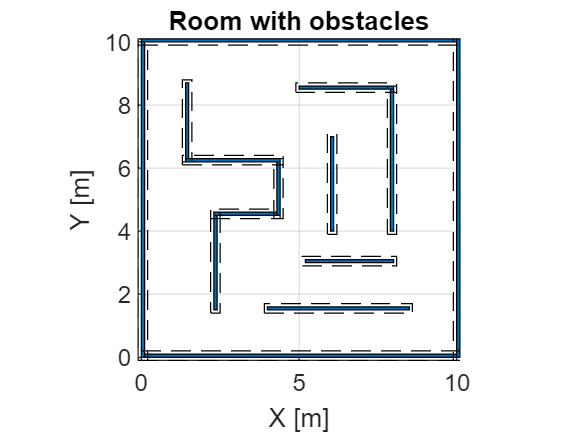

figure;
for i = 1:size(obstacles, 1)
    rectangle('Position', obstacles(i, :), 'FaceColor', '#0072BD');
end

hold on;
for i = 1:size(inflated_obstacles, 1)
    rectangle('Position', inflated_obstacles(i, :), 'EdgeColor', 'k', 'LineStyle', '--');
end

grid on;
axis equal; 
xlabel('X [m]');
ylabel('Y [m]');
xlim([-0.10 x_map_size + 0.1]);
ylim([-0.10 y_map_size + 0.1]);
title('Room with obstacles');
hold off;

## Build the RRT algorith to explore the space

% Parameter declaration
step_size = 0.05; 
n_iterations = 1000; 
goal_threshold = 0.5; 

% RRT initialization
rrt_tree = start; % RRT starting point
parent_indices = 0; % RRT parent index

% RRT tree generation
for i = 1:n_iterations

    % Random point (MODIFY HERE THE EXPLORATION SPACE FOR EACH DRONE IF REQUIRED)
    random_point = [rand() * x_map_size, rand() * y_map_size];

    % If point is inside the obstacles, avoid
    if isInObstacle(random_point, inflated_obstacles)
        continue;
    end

    % Find nearest point wrt RRT tree
    distances = sqrt(sum((rrt_tree - random_point).^2, 2));
    [min_distance, nearest_idx] = min(distances);

    % Identify new RRT point
    direction = random_point - rrt_tree(nearest_idx, :);
    unit_direction = direction / norm(direction);
    new_point = rrt_tree(nearest_idx, :) + step_size * unit_direction;

    % Check compenetrarion of new point wrt the obstacles
    if isInObstacle(new_point, inflated_obstacles)
        continue;
    end

    % Add the new point to the RRT tree
    rrt_tree = [rrt_tree; new_point];
    parent_indices = [parent_indices; nearest_idx];

    % % Verify if the goal is reached
    % if norm(new_point - goal) < goal_threshold
    %     disp('Goal raggiunto!');
    %     break;
    % end
end

Visualize RRT tree on the map

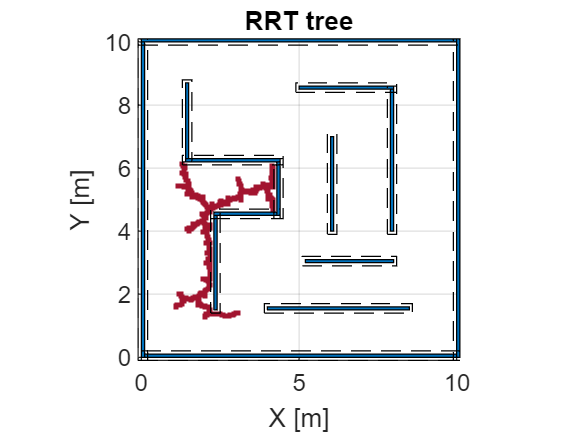

figure;
hold on;
%plot(rrt_tree(:, 1), rrt_tree(:, 2), 'O'); % Visualizza i punti
for i = 2:size(rrt_tree, 1)
    plot([rrt_tree(parent_indices(i), 1), rrt_tree(i, 1)], ...
         [rrt_tree(parent_indices(i), 2), rrt_tree(i, 2)], 'LineStyle', '-', 'Color', '#A2142F', 'Marker' , '.');
end

for i = 1:size(obstacles, 1)
    rectangle('Position', obstacles(i, :), 'FaceColor', '#0072BD');
end

hold on;
for i = 1:size(inflated_obstacles, 1)
    rectangle('Position', inflated_obstacles(i, :), 'EdgeColor', 'k', 'LineStyle', '--');
end

grid on;
axis equal; 
xlabel('X [m]');
ylabel('Y [m]');
xlim([-0.10 x_map_size + 0.1]);
ylim([-0.10 y_map_size + 0.1]);
title('RRT tree');
hold off;

## LiDAR test

lidar_position = [5, 4];
lidar_angles = linspace(0, 360, 100);  % 100 scanning lines
max_range = 2;
lidar_dist_res = 0.01; 
[out1,out2] = Lidar_scan(obstacles, lidar_position, lidar_angles, max_range, lidar_dist_res);

Plot Lidar example

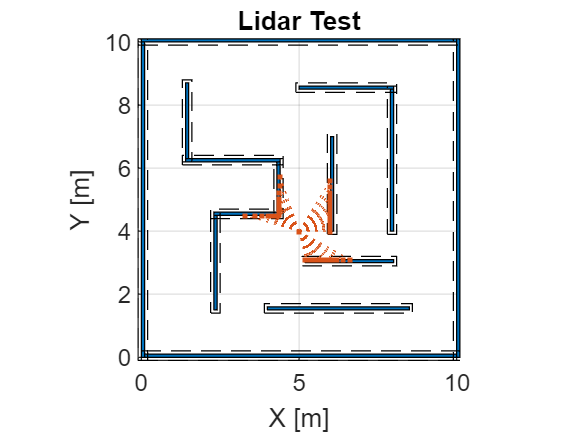

figure();
% Plot obstacles
for i = 1:size(obstacles, 1)
    hold on
    rectangle('Position', obstacles(i, :), 'FaceColor', '#0072BD');
end
% Plot inflated obstacles
for i = 1:size(inflated_obstacles, 1)
    rectangle('Position', inflated_obstacles(i, :), 'EdgeColor', 'k', 'LineStyle', '--');
end
% Plot LiDAR result
for angle_step = 1:length(lidar_angles)-1
    angle = lidar_angles(angle_step);
    ray_direction = [cosd(angle), sind(angle)];
    hit_point = out1(angle_step, :);
    if ~all(hit_point == 0) % Plot just hit points
        
        plot([lidar_position(1), hit_point(1)], [lidar_position(2), hit_point(2)],'LineStyle', ':', 'Color', '#D95319', 'Marker' , "."'); % Plot ray
    end
end
grid on;
axis equal; 
xlabel('X [m]');
ylabel('Y [m]');
xlim([-0.10 x_map_size + 0.1]);
ylim([-0.10 y_map_size + 0.1]);
title('Lidar Test');
hold off;